# Lab3 DC motor drive modelling

Tmdl = 10;
load("var_94.mat");
modelName = 'lab2s.slx'

modelName = 'lab2s.slx'

## 1. Control by amature voltage change

ua_list = [1, 0.8, 0.6, 0.4, 0.2];
t_list = cell(1, 5);
torq_list = cell(1, 5);
w_list = cell(1, 5);

ue = Uex;
Tmdl = 100;
radd = 0;
Ua_change = 0;
r1 = 0;
r2 = 0;
r3 = 0;

warning off
for i = 1:length(ua_list)
    ua = ua_list(i)*Uanom;
    SimOut = sim(modelName, 'ReturnWorkspaceOutputs', 'on');
    t_list{i} = SimOut.yout.get('torque').Values.Time;
    torq_list{i} = SimOut.yout.get('torque').Values.Data;
    w_list{i} = SimOut.yout.get('velocity').Values.Data;
end
warning on

#### PLOTS

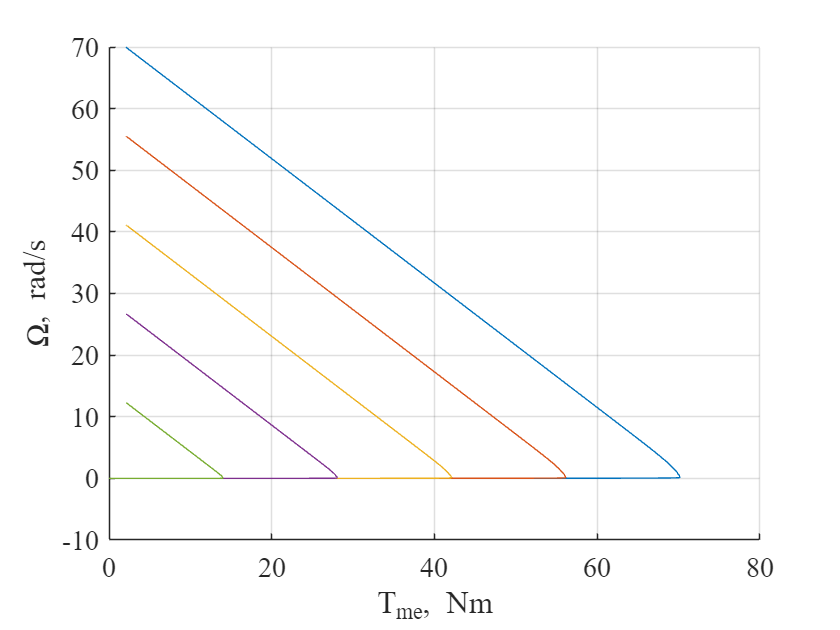

h = figure;
set(h,'DefaultAxesFontSize',14);
set(h,'DefaultAxesFontName','Times New Roman');
grid on
hold on
for i = 1:length(ua_list)
    plot(torq_list{i}(t_list{i}>1),w_list{i}(t_list{i}>1))
end
ylabel('\Omega, \itrad\rm/\its')
xlabel('\itT_{me}\rm, \itNm')

## 2. Control by flux change


ue_list = [1, 0.8, 0.6, 0.4, 0.2];
t_list2 = cell(1, 5);
torq_list2 = cell(1, 5);
w_list2 = cell(1, 5);

ua = Uanom;
Tmdl = 100;
radd = 0;
Ua_change = 0;

warning off
for i = 1:length(ue_list)
    ue = ue_list(i)*Uex;
    SimOut2 = sim(modelName, 'ReturnWorkspaceOutputs', 'on');
    t_list2{i} = SimOut2.yout.get('torque').Values.Time;
    torq_list2{i} = SimOut2.yout.get('torque').Values.Data;
    w_list2{i} = SimOut2.yout.get('velocity').Values.Data;
end

#### PLOTS

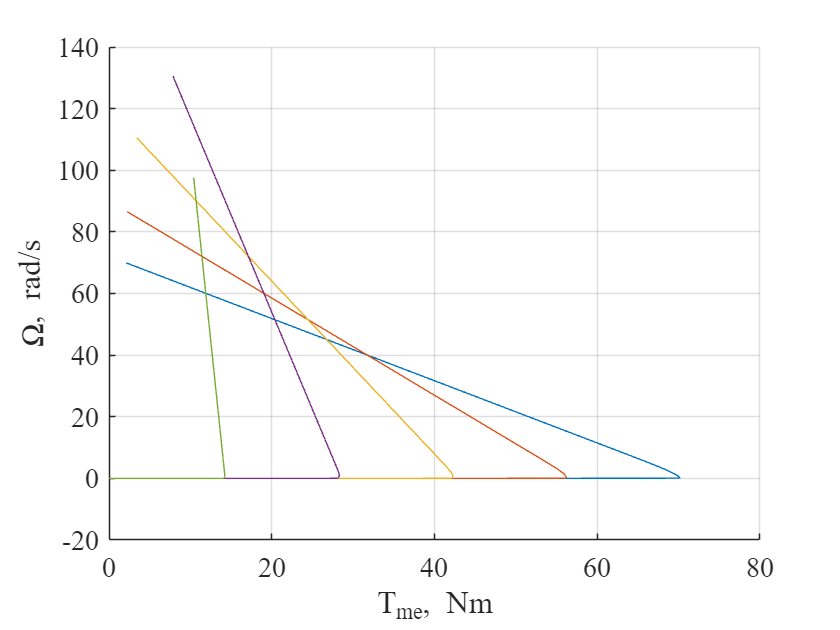

h = figure;
set(h,'DefaultAxesFontSize',14);
set(h,'DefaultAxesFontName','Times New Roman');
grid on
hold on
for i = 1:length(ua_list)
    plot(torq_list2{i}(t_list2{i}>1),w_list2{i}(t_list2{i}>1))
end
ylabel('\Omega, \itrad\rm/\its')
xlabel('\itT_{me}\rm, \itNm')

## 3. Simulating of braking modes

### a. Simulation of reverse braking by adding resistance *R**add*.

ua_list = [1, 0.8, 0.6, 0.4, 0.2];
t_list = cell(1, 5);
torq_list = cell(1, 5);
w_list = cell(1, 5);

ua = Uanom;
ue = Uex;
Tmdl = 100;
radd = Radd;

warning off
i = 1;
SimOut = sim(modelName, 'ReturnWorkspaceOutputs', 'on');
t_list{i} = SimOut.yout.get('torque').Values.Time;
torq_list{i} = SimOut.yout.get('torque').Values.Data;
w_list{i} = SimOut.yout.get('velocity').Values.Data;

warning on

#### PLOTS

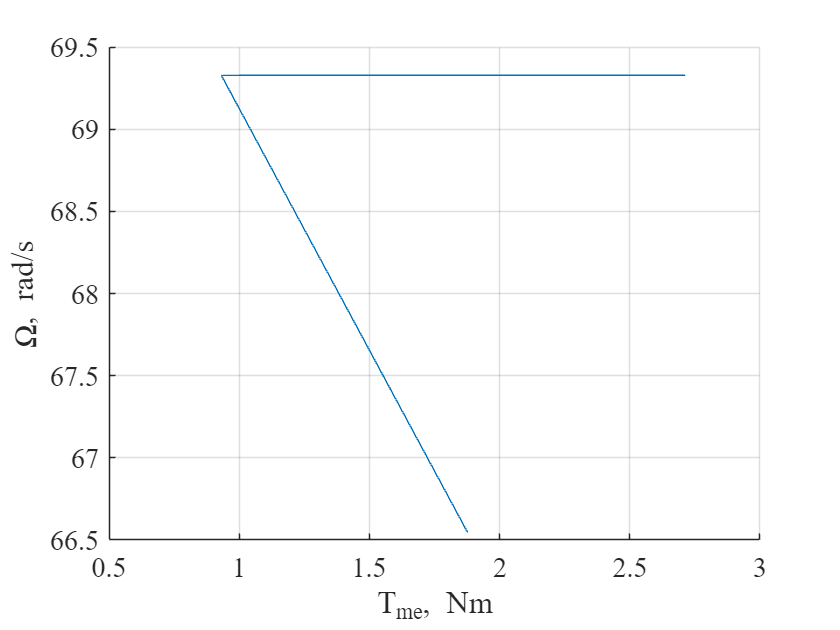

h = figure;
set(h,'DefaultAxesFontSize',14);
set(h,'DefaultAxesFontName','Times New Roman');
grid on
hold on

plot(torq_list{i}(t_list{i}>50),w_list{i}(t_list{i}>50))

ylabel('\Omega, \itrad\rm/\its')
xlabel('\itT_{me}\rm, \itNm')

### b. Simulation of dynamic braking by disconnecting converter and connecting resistance Radd.

ua_list = [1, 0.8, 0.6, 0.4, 0.2];
t_list = cell(1, 5);
torq_list = cell(1, 5);
w_list = cell(1, 5);

ua = Uanom;
ue = Uex;
Tmdl = 100;
radd = Radd;
Ua_change = ua;

warning off
i = 1;
SimOut = sim(modelName, 'ReturnWorkspaceOutputs', 'on');
t_list{i} = SimOut.yout.get('torque').Values.Time;
torq_list{i} = SimOut.yout.get('torque').Values.Data;
w_list{i} = SimOut.yout.get('velocity').Values.Data;

warning on

#### PLOTS

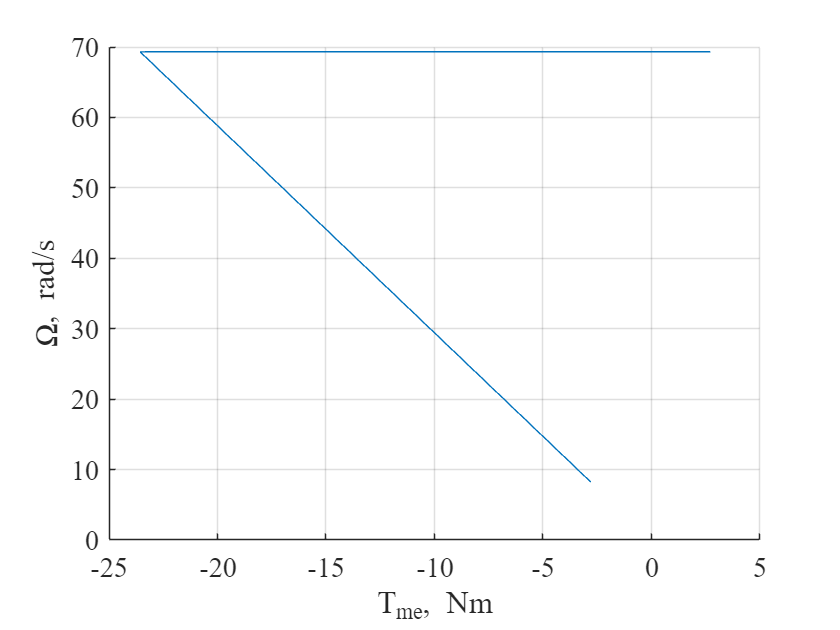

h = figure;
set(h,'DefaultAxesFontSize',14);
set(h,'DefaultAxesFontName','Times New Roman');
grid on
hold on

plot(torq_list{i}(t_list{i}>50),w_list{i}(t_list{i}>50))

ylabel('\Omega, \itrad\rm/\its')
xlabel('\itT_{me}\rm, \itNm')

### b. Simulation of regenerative braking by changing armature voltage from Unom to 0.8Unom.

ua_list = [1, 0.8, 0.6, 0.4, 0.2];
t_list = cell(1, 5);
torq_list = cell(1, 5);
w_list = cell(1, 5);

ua = Uanom;
ue = Uex;
Tmdl = 100;
radd = Radd;
Ua_change = 0.2*ua;

warning off
i = 1;
SimOut = sim(modelName, 'ReturnWorkspaceOutputs', 'on');
t_list{i} = SimOut.yout.get('torque').Values.Time;
torq_list{i} = SimOut.yout.get('torque').Values.Data;
w_list{i} = SimOut.yout.get('velocity').Values.Data;

warning on

#### PLOTS

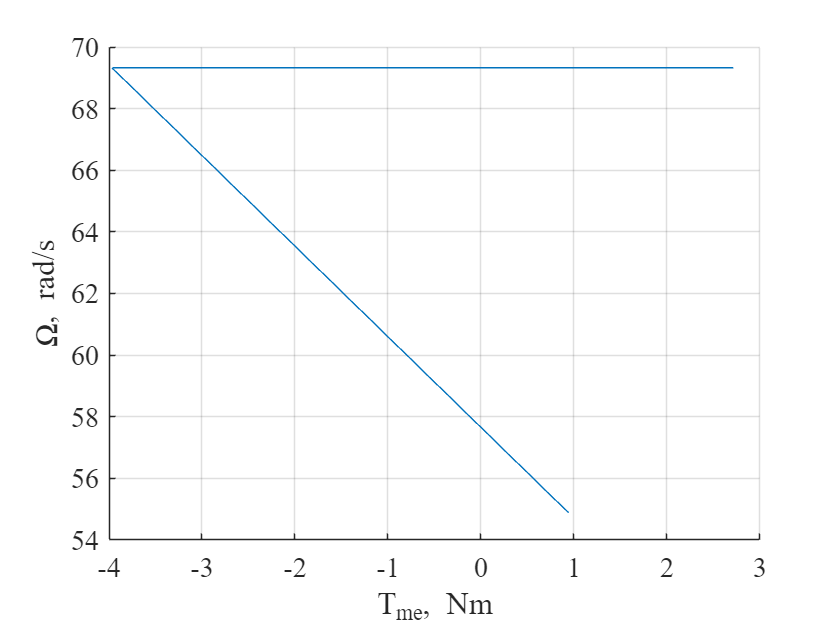

h = figure;
set(h,'DefaultAxesFontSize',14);
set(h,'DefaultAxesFontName','Times New Roman');
grid on
hold on

plot(torq_list{i}(t_list{i}>50),w_list{i}(t_list{i}>50))

ylabel('\Omega, \itrad\rm/\its')
xlabel('\itT_{me}\rm, \itNm')

## 4. **Simulation of starting of the DC motor.**

### a. Simulation of direct starting of the DC motor.

ua_list = [1, 0.8, 0.6, 0.4, 0.2];
t_list = cell(1, 5);
torq_list = cell(1, 5);
w_list = cell(1, 5);
i_list = cell(1, 5);

ua = Uanom;
ue = Uex;
Tmdl = 100;
radd = 0;
Ua_change = 0;

warning off
i = 1;
SimOut = sim(modelName, 'ReturnWorkspaceOutputs', 'on');
t_list{i} = SimOut.yout.get('torque').Values.Time;
torq_list{i} = SimOut.yout.get('torque').Values.Data;
w_list{i} = SimOut.yout.get('velocity').Values.Data;
i_list{i} = SimOut.yout.get('ia').Values.Data;

warning on

#### PLOTS

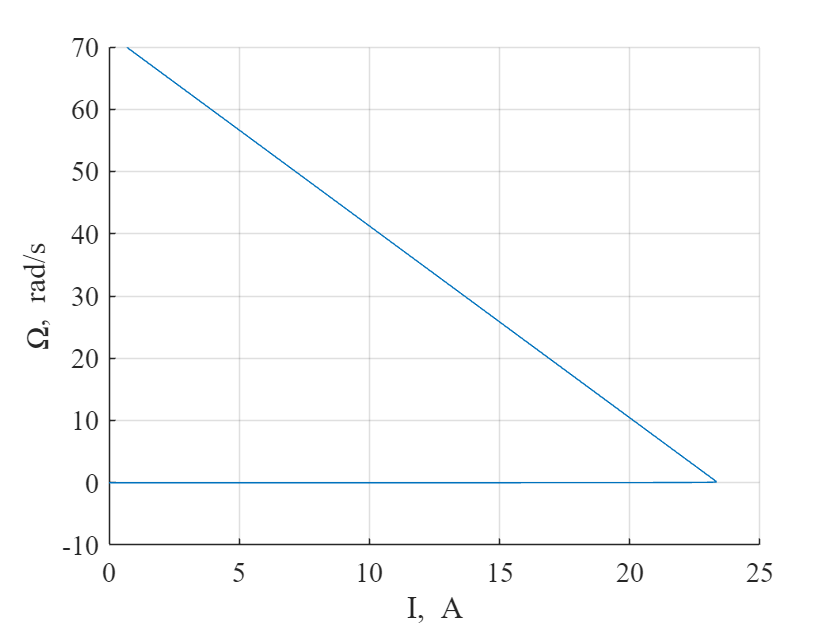

h = figure;
set(h,'DefaultAxesFontSize',14);
set(h,'DefaultAxesFontName','Times New Roman');
grid on
hold on

plot(i_list{i}, w_list{i})

ylabel('\Omega, \itrad\rm/\its')
xlabel('\itI\rm, \itA')

### b. Starting of the DC motor with additional resistances.

kst = 1/(10*k*Lex*Uex/Rex)

kst = 0.3276

ua_list = [1, 0.8, 0.6, 0.4, 0.2];
t_list = cell(1, 5);
torq_list = cell(1, 5);
w_list = cell(1, 5);
i_list = cell(1, 5);

ua = Uanom;
ue = Uex;
Tmdl = 100;
radd = 0;
Ua_change = 0;
r1 = R1;
r2 = R2;
r3 = R3;

warning off
i = 1;
SimOut = sim(modelName, 'ReturnWorkspaceOutputs', 'on');
t_list{i} = SimOut.yout.get('torque').Values.Time;
torq_list{i} = SimOut.yout.get('torque').Values.Data;
w_list{i} = SimOut.yout.get('velocity').Values.Data;
i_list{i} = SimOut.yout.get('ia').Values.Data;

warning on

#### PLOTS

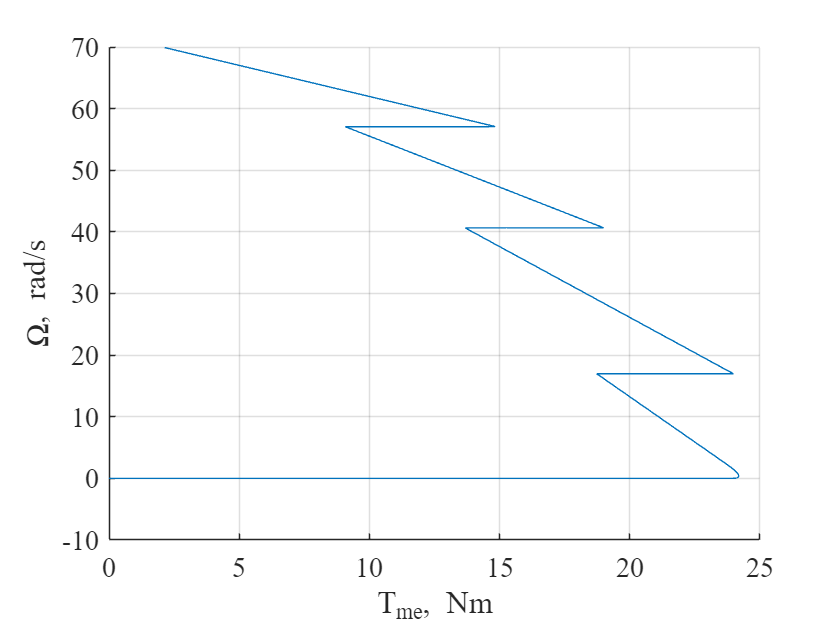

h = figure;
set(h,'DefaultAxesFontSize',14);
set(h,'DefaultAxesFontName','Times New Roman');
grid on
hold on

plot(torq_list{i}, w_list{i})

ylabel('\Omega, \itrad\rm/\its')
xlabel('\itT_{me}\rm, \itNm')

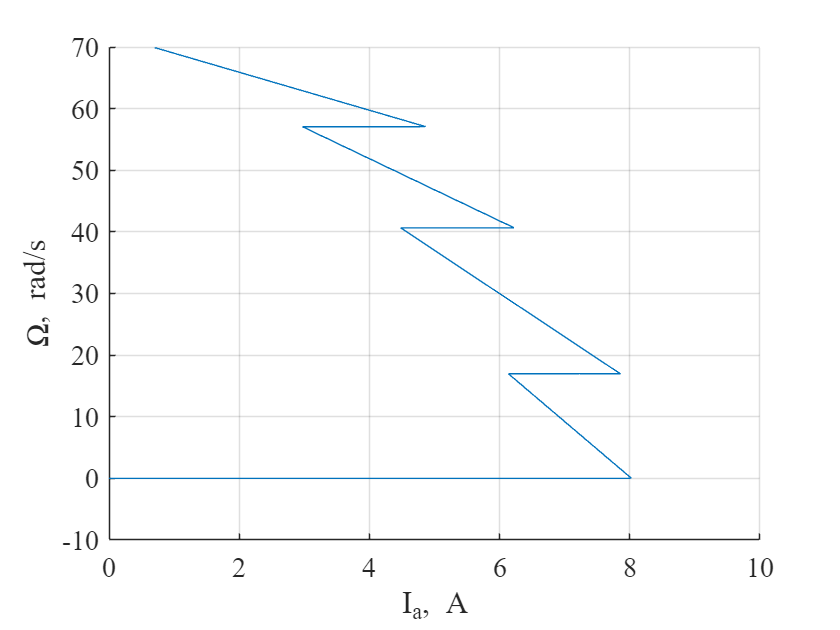


h = figure;
set(h,'DefaultAxesFontSize',14);
set(h,'DefaultAxesFontName','Times New Roman');
grid on
hold on

plot(i_list{i}, w_list{i})

ylabel('\Omega, \itrad\rm/\its')
xlabel('\itI_a\rm, \itA')